clc;clear;
load("/home/dellx/文档/uhd/host/Simulation_RU/Simulation_RU/2tx_x2_heltf160_withoutCP.mat")
data = read_complex_binary('/mnt/tmp/1016_x2_withoutCP_tx1_pmz_breathe.dat'); 
% data_csv = readmatrix('/mnt/tmp/usrp_160_breathe1.csv', 'HeaderLines', 1);
temp = csvread('/mnt/tmp/1016_x2_withoutCP_tx1_pmz_breathe.csv',1,0);
i = 4;
% symbollen_table = [288, 576, 1152, 2304];
symbollen_table = [256, 512, 1024, 2048];
gilen_table = [32, 64, 128, 256];
symbollen = symbollen_table(i);
gilen = gilen_table(i);
data1 = [data(257-256:end); zeros(symbollen - mod(length(data(257-256:end)), symbollen), 1)];
data1 = reshape(data1, [symbollen, length(data1) / symbollen]);

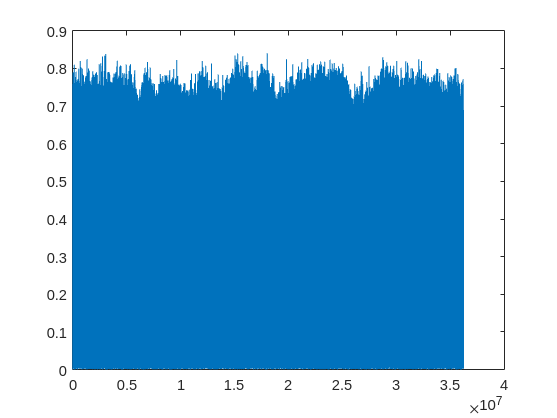

% numfram=10;
% for i=1:(numfram-1)*framelen
%     cp_win1=abs(data(i:i+gilen-1));
%     cp_win2=abs(data(i+symbollen:i+framelen-1));
%     findpoint(i)=(cp_win1-cp_win2)'*(cp_win1-cp_win2);
% end
% 
% [~,sorted_indices]=sort(abs(findpoint),'ascend');
% detacir=400;
% cir13=cir1;
% cir13=circshift(cir13,detacir,1);
% figure
% imagesc(abs(cir13));
% title('循环移位');
% axis xy;
% figure
% plot(abs(data2(1:end)))
% hold on;
figure
plot(abs(data(1:end)))
hold on;

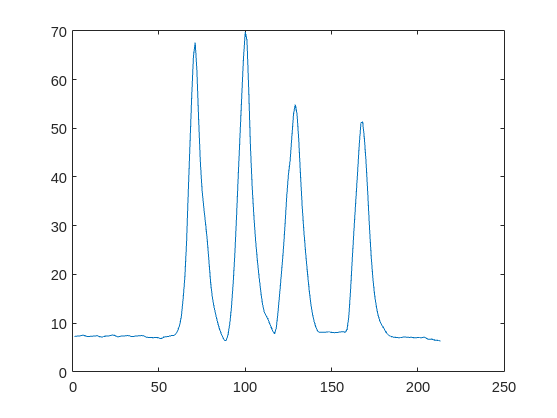

figure
plot(abs(temp(1:end)))
hold on; 

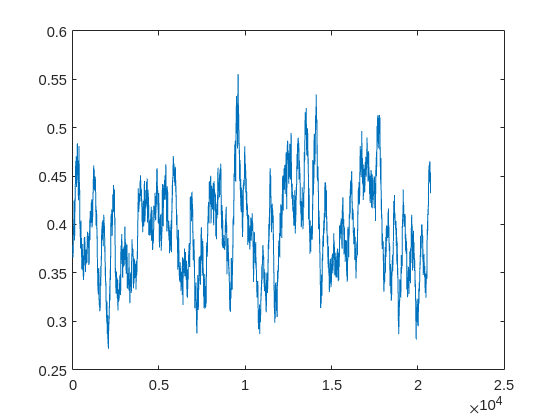

framelen = symbollen + gilen;
findpoint = zeros(1, length(data1(1,:)));
numfram=10;
for i=1:(numfram-1)*framelen
cp_win1=abs(data(i:i+gilen-1));
cp_win2=abs(data(i+symbollen:i+framelen-1));
findpoint(i)=(cp_win1-cp_win2)'*(cp_win1-cp_win2);
end
[~,sorted_indices]=sort(abs(findpoint),'ascend');
[~,oneposition]=min(findpoint);
figure
plot(abs(findpoint))
hold on

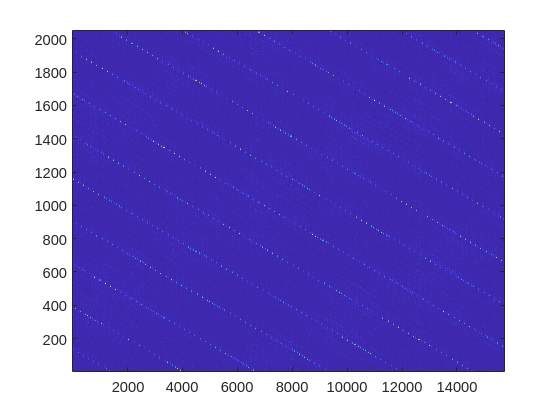

% data1 = [data(oneposition-256:end); zeros(symbollen - mod(length(data(oneposition-256:end)), symbollen), 1)];
% data1 = reshape(data1, [symbollen, length(data1) / symbollen]);
% 
% data2=lowpass(data,0.25);
% 
% cfr_all=fftshift(fft(data1(1:end,:)));
% user = 1;
% cir2=ifft(fftshift(cfr_all.*conj(cfg.userltf(user,:)'))); %convolution
% corr_result = conv(data(1:6000), bb(user,257:end));
% figure
% plot(abs(corr_result))
% hold on
% figure
% imagesc(abs(cir2(:,1:2000)))
% hold on% xlim([1 500])


data=data(oneposition:end);
data=data(1:floor(length(data)/framelen)*framelen);
data=reshape(data,framelen,length(data)/framelen);
data=data(gilen+1:end,:);
cfr_all=fftshift(fft(data));
user = 1;
cir2=ifft(fftshift(cfr_all.*conj(cfg.userltf(user,:).'))); %convolution
figure 
imagesc(abs(cir2));
axis xy

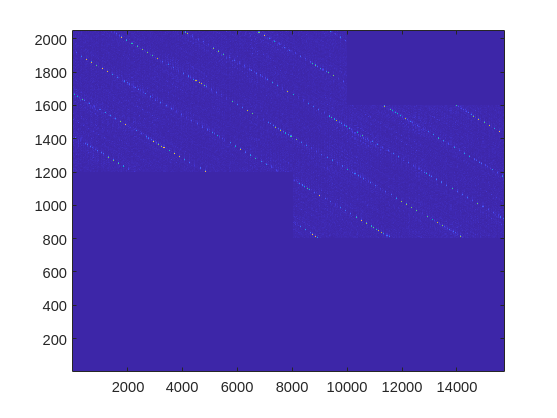

cir11=cir2;
cir11(1:1200,1:8000)=0;
cir11(1600:end,10000:end)=0;
cir11(1:800,:)=0;
figure
imagesc(abs(cir11));
axis xy

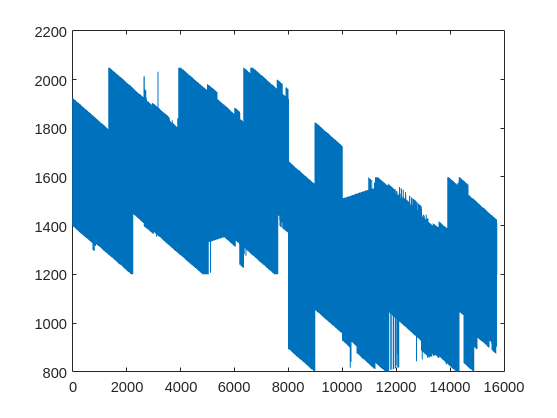

[cir_value,max_index]=max(abs(cir11));
figure
plot(max_index)

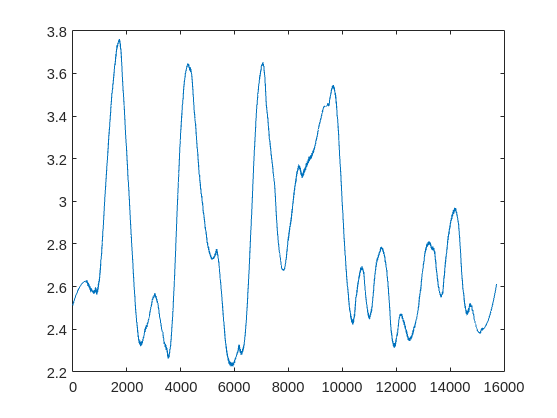

disub=-1;
value2=zeros(size(cir11,2),1);
for i=1:size(cir11,2)
    value2(i)=abs(cir11(max_index(i)+disub,i));
end
figure
plot(smoothdata(value2,'sgolay',1000))